# MoLS Abundance Estimates for US Capital Cities

MoLS was run for capital city locations in the continental US. Coordinates (latitude and longitude) were obtained from [John Burkardt's site at FSU](https://people.sc.fsu.edu/~jburkardt/datasets/states/state_capitals_ll.txt) (see Capital_Cities_cont_US.xlsx in this folder). Meteorological data from 2011 to 2020 was then extracted from files downloaded from the [MACA website](http://www.climatologylab.org/maca.html).

## Sensitivity to Location

The plot below compares two runs of MoLS on the Canadian model in nearby locations (Sacramento city versus the centroid of Sacramento County). Note that mostly peak heights, but sometimes season lengths are affected by minor changes in location.

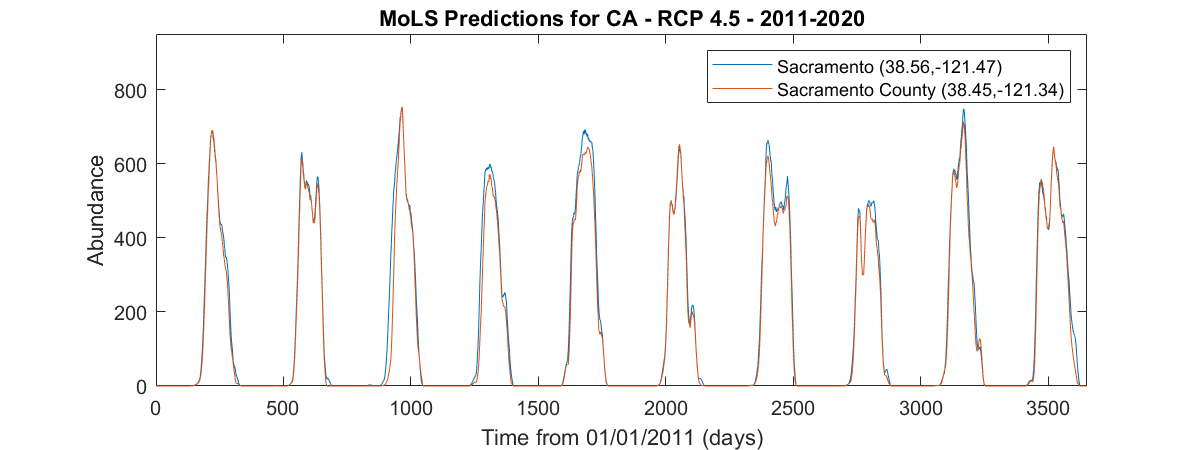

model = 'CanESM2';
[A,~,~]=xlsread(['../data/2011-2020_rcp45_' model '_CA.csv']);
[B,~,~]=xlsread('../data/2011-2020_rcp45_CanESM2_Sacramento.csv');
figure(); set(gcf,'Position',[0 0 800 300]);
TA=datenum(A(:,1),A(:,2),A(:,3)); TB=datenum(B(:,1),B(:,2),B(:,3));
plot(TA-TA(1),A(:,10),TB-TA(1),B(:,10)); xlim([0 TA(end)-TA(1)]);
title('MoLS Predictions for CA - RCP 4.5 - 2011-2020'); ylim([0 950])
xlabel('Time from 01/01/2011 (days)'); ylabel('Abundance');
legend('Sacramento (38.56,-121.47)', 'Sacramento County (38.45,-121.34)')

## Sensitivity to Climate Model

The plot below shows MoLS predictions in Phoenix, AZ, for the Canadian and the US models.

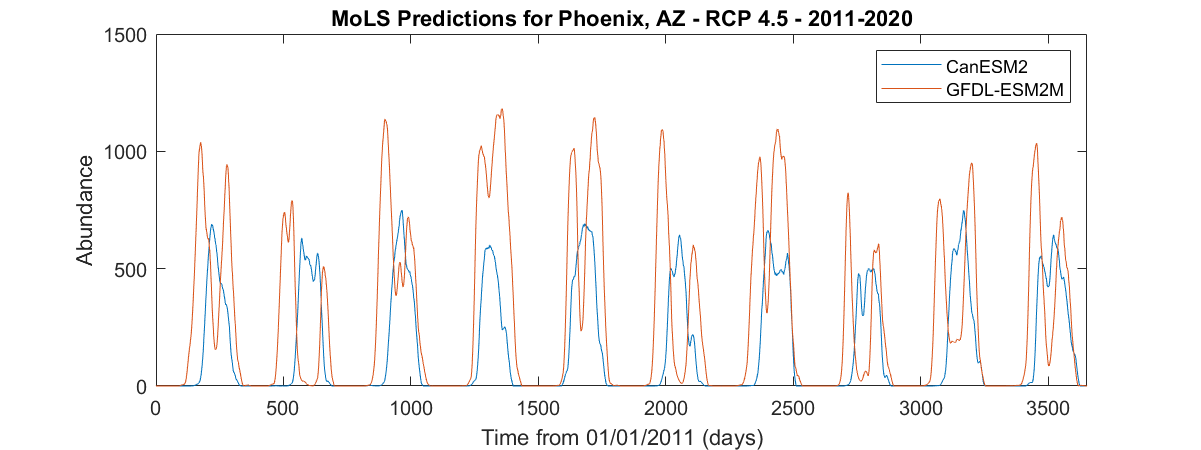

[A,~,~]=xlsread(['../data/2011-2020_rcp45_' model '_CA.csv']);
[B,~,~]=xlsread('../data/historical_rcp45_33.45_-112.07.csv');
figure(); set(gcf,'Position',[0 0 800 300]);
TA=datenum(A(:,1),A(:,2),A(:,3)); TB=datenum(B(:,1),B(:,2),B(:,3));
plot(TA-TA(1),A(:,10),TB-TA(1),B(:,10)); xlim([0 TA(end)-TA(1)]);
xlabel('Time from 01/01/2011 (days)'); ylabel('Abundance');
title('MoLS Predictions for Phoenix, AZ - RCP 4.5 - 2011-2020'); ylim([0 1500])
legend(model, 'GFDL-ESM2M')

As shown below, weather predictions significantly differ between models.

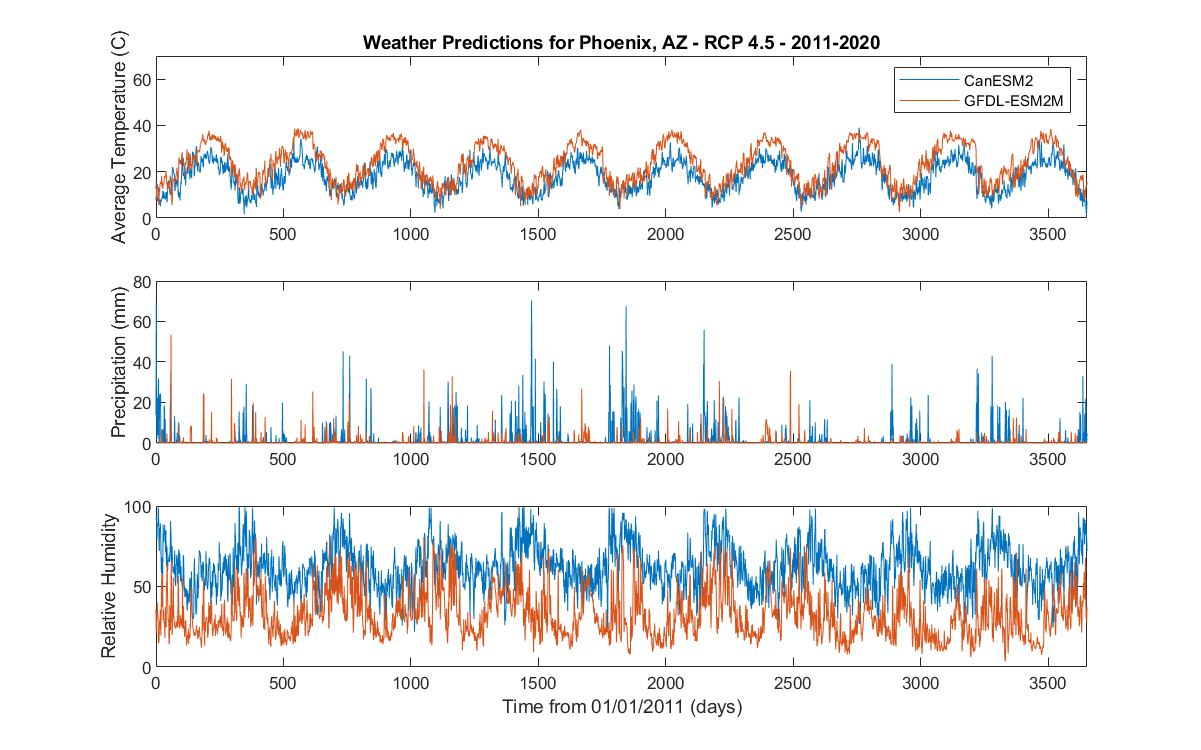

figure(); set(gcf,'Position',[0 0 800 500]);
subplot(3,1,1)
plot(TA-TA(1),A(:,7),TB-TA(1),B(:,7)); xlim([0 TA(end)-TA(1)]);
ylabel('Average Temperature (C)');
title('Weather Predictions for Phoenix, AZ - RCP 4.5 - 2011-2020');
ylim([0 70]); legend(model, 'GFDL-ESM2M')
subplot(3,1,2)
plot(TA-TA(1),A(:,6),TB-TA(1),B(:,6)); xlim([0 TA(end)-TA(1)]);
% ylim([0 80]); legend(model, 'GFDL-ESM2M')
ylabel('Precipitation (mm)');
subplot(3,1,3)
plot(TA-TA(1),A(:,9),TB-TA(1),B(:,9)); xlim([0 TA(end)-TA(1)]);
% ylim([0 150]); legend(model, 'GFDL-ESM2M')
xlabel('Time from 01/01/2011 (days)'); ylabel('Relative Humidity');